# INF250 - CA4 - Deadline 23/4 @ 23:59

### Upload your CA4_<your_mitt_id>.mlx submission on Mitt, make sure it is the correct version and double-check (for example by downloading and running it again) to make sure you submitted the right file!

During the fourth round of programming assignments, we focus on an iterative optimization algorithms, namely gradient ascent/descent.

## Part 1 - Gradient descent (60%)

There are many ways to visualize the solutions to a 2D function f(x,y) across a span of function arguments. One way is to draw a heatmap, where the x and y coordinates denotes the respective function arguments, and the color/saturation of the heatmap denotes the result of the function in said coordinates. 

[https://en.wikipedia.org/wiki/Heat_map](https://en.wikipedia.org/wiki/Heat_map)

Another way is to draw a surface in 3D, where the x and y coordinates again denotes the respective function arguments, but instead of using color/saturation, the z axis (the surface height) denotes the result of the function in said coordinates.

[https://en.wikipedia.org/wiki/Graph_of_a_function#Functions_of_two_variables](https://en.wikipedia.org/wiki/Graph_of_a_function#Functions_of_two_variables)

A third option would be a contour map.

[https://en.wikipedia.org/wiki/Contour_line](https://en.wikipedia.org/wiki/Contour_line)

And there are many more options. For this assignment you will mainly use a heatmap and a surface map; but you are welcome (encouraged, in fact!) to try to visualize your solution in any other way you see fit.

### 1a: Generate and visualize a matrix of function solutions (10%)

First, create a nxn matrix of solutions to the equation  $f\left(x,y\right)=\sin \left(\frac{\left(x*2\pi \right)}{n}\right)+\cos \left(\frac{\left(y*2\pi \right)}{n}\right)$ with n = 32, x = matrix row, y = matrix column.

You are not allowed to use loops for this part, but you are provided matrices you can use to generate the solution matrix. Try to really understand why this matrix contains the results of f(x,y) over the function span n.

**Hint**: *A 32x2 matrix multiplied with a 2x32 matrix will give you a 32x32 matrix. *

n = 32;                                 % function span
Ones = ones(1,n);                       % row of ones
row = [1:n];                            % row of increasing axis number
xVar = (row*2*pi/n);                    % ((x*2*pi)/n)
yVar = (row*2*pi/n);                    % ((y*2*pi)/n)
xFactor = 1.0;                          % factor of sin((x*2*pi)/n)
yFactor = 1.0;                          % factor of cos((y*2*pi)/n)
Fx = [sin(xVar); (Ones*yFactor)]

Fx =     0.1951    0.3827    0.5556    0.7071    0.8315    0.9239    0.9808    1.0000    0.9808    0.9239    0.8315    0.7071    0.5556    0.3827    0.1951    0.0000   -0.1951   -0.3827   -0.5556   -0.7071   -0.8315   -0.9239   -0.9808   -1.0000   -0.9808   -0.9239   -0.8315   -0.7071   -0.5556   -0.3827   -0.1951   -0.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Fy = [(Ones*xFactor)' cos(yVar)']

Fy =     1.0000    0.9808
    1.0000    0.9239
    1.0000    0.8315
    1.0000    0.7071
    1.0000    0.5556
    1.0000    0.3827
    1.0000    0.1951
    1.0000    0.0000
    1.0000   -0.1951
    1.0000   -0.3827



%TODO

solutionMatrix = Fy * Fx;  %Create a solution matrix as stated in the hint

Now, visualize the matrix using the matlab functions pcolor, colormap and colorbar.

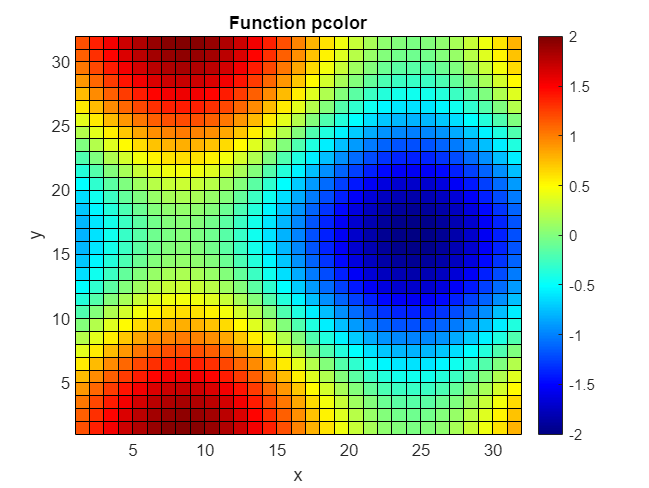

%TODO
figure;
pcolor(solutionMatrix);
title('Function pcolor');
xlabel('x');
ylabel('y');
colormap(jet);
colorbar;

Also, visualize the matrix using the matlab function surf.

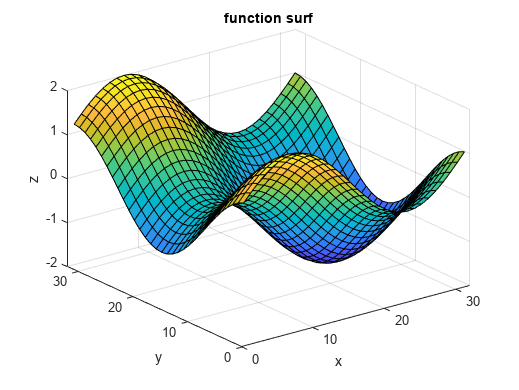

%TODO
figure;
surf(solutionMatrix);
title('function surf');
xlabel('x');
ylabel('y');
zlabel('z');

### 1b: Generate and visualize a matrix of function derivatives/gradients (20%)

There are also more than one way to visualize the derivatives of a 2D function; you will use an arrow plot/vector field, but again, if you can think of any other way to visualize it, you are welcome to do so.

[https://en.wikipedia.org/wiki/Vector_field](https://en.wikipedia.org/wiki/Vector_field)

For each matrix coordinate, calculate the gradient of the function as a 2D vector. I remind you, the function to derive is:


$$f\left(x,y\right)=\sin \left(\frac{\left(x*2\pi \right)}{n}\right)+\cos \left(\frac{\left(y*2\pi \right)}{n}\right)$$


where n is the constant 32, x is the row, and y is the column. Store the resulting vectors such that you can retrieve them for any coordinate in the relevant coordinate span. Also: Remember that the gradient points in the direction of steepest *ascent*. For steepest *descent* you will need the negative of the gradient vector.

% For each tile (x,y): x = df/dx, y = df/dy
%TODO

% Initialize matrices for the gradients
grad_x = zeros(n);
grad_y = zeros(n);

% Compute the partial derivatives using loops
for i = 1:n
    for j = 1:n
        x = xVar(j);
        y = yVar(i);
        df_dx = cos(x) * ((2*pi)/n);
        df_dy = -sin(y) * ((2*pi)/n);
        
        % Calculate the gradient vector field for steepest descent (negative of the gradient)
        grad_x(i, j) = -df_dx;
        grad_y(i, j) = -df_dy;
    end
end


Visualize using the matlab function quiver.

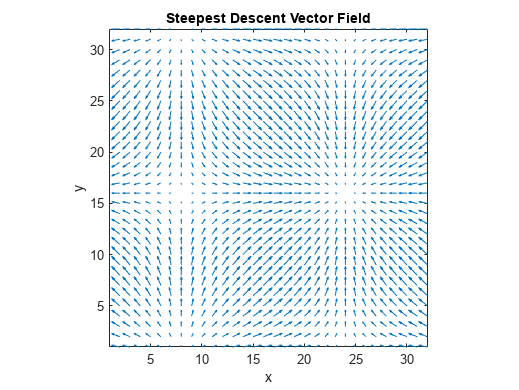

figure;
quiver(row', row', grad_x, grad_y);
title('Steepest Descent Vector Field');
xlabel('x');
ylabel('y');
xticks(0:5:n); yticks(0:5:n);
axis equal;
% Done to fit the figure
ax = gca;
ax.XLim = [1 n];
ax.YLim = [1 n];
ax.DataAspectRatio = [1 1 1];

### 1c: Perform gradient descent (30%)

Now that you have a 32x32 map of function values and their gradients, write a function for gradient descent from any start coordinate (within the function span). Visualize the resulting descent from at least four different starting points by plotting each landing point onto the function colormap you made in 1a, using the matlab functions scatter (for points) and plot (for lines between them). 

You are not expected to reach the optimal coordinate from any other coordinate. For some start coordinates, the gradient descent will move out of the function span.

**Hints**: 

- *Here you should use a loop. For each step, query the vector field for step direction/magnitude. Use a stepsize/tau variable as an additional factor.*

- *Since the gradient vectors are stored at discrete coordinates, but each step landing point might be "between" coordinates, you might want to interpolate to retrieve better gradient values. For instance, lets say you land at point (15.3, 21.2); There exists no x coordinate 15.3 in the matrix, only 15 or 16. You could round to the nearest coordinate - round(15.3) = 15, and retrieve the vector value at that coordinate. A better solution would be to interpolate linearly: linearInterpolate(15.3) = 0.7 * value at x-coordinate 15 + 0.3 * value at x-coordinate 16. Then you do the same for y: linearInterpolate(21.2) = 0.8 * value at y-coordinate 21 + 0.2 * value at y-coordinate 22. A different option could be to calculate the gradient analytically for each coordinate with a function, instead of retrieving it from the vector field matrix. Even another option could be to use a central difference function to estimate a gradient at each coordinate. You are free to choose whichever method you want - as long as it works!*

- *Select tau (the stepsize) empirically (meaning: test out different values and see which works best). You can, for example, start with tau=5.*

- *You will need to break the loop if the descent leaves the bounds of the matrix. For instance, if you start the descent in a bad location, like (5,10).You also need to define a maximum number of iterations to prevent infinite loops.*

- *You can stop the loop early by checking for suitable conditions, like the length of the previous step.*

- *For bonus point: try to implement momentum as well, or some other algorithm enhancement of your choice: *[*https://machinelearningmastery.com/gradient-descent-with-momentum-from-scratch/*](https://machinelearningmastery.com/gradient-descent-with-momentum-from-scratch/)

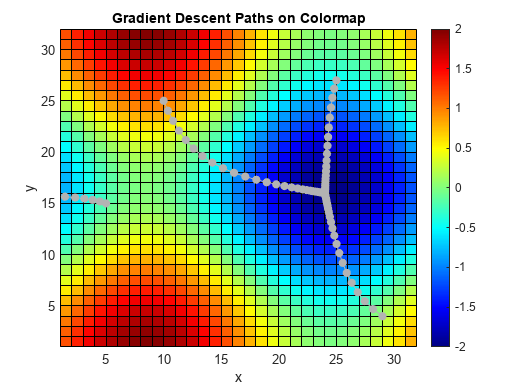

% Starting points
start_points = ...
    [5, 15;
    10, 25;
    25, 27;
    29, 4];

tau = 5;
max_iter = 100;

% Perform gradient descent for each starting point
paths = cell(1, 4);
for i = 1:4
    start_x = start_points(i, 1);
    start_y = start_points(i, 2);
    paths{i} = gradient_descent(start_x, start_y, grad_x, grad_y, tau, max_iter); %%Function at the end of the file
end

% Visualize the function colormap
figure;
pcolor(solutionMatrix);
colormap(jet);
colorbar;
hold on;

% Plot the gradient descent paths with the color gray
gray = [.7 .7 .7];
for i = 1:4
    scatter(paths{i}(:, 1), paths{i}(:, 2), 30, 'MarkerEdgeColor', gray, 'MarkerFaceColor', gray);
    plot(paths{i}(:, 1), paths{i}(:, 2), 'Color', gray);
end

hold off;
title('Gradient Descent Paths on Colormap');
xlabel('x');
ylabel('y');

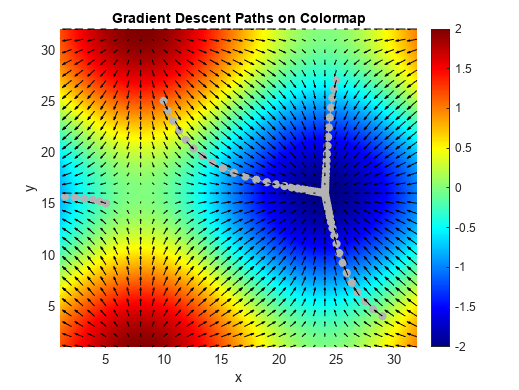


% Visualize the function colormap
figure;
pcolor(solutionMatrix);
shading 'interp';
colormap(jet);
colorbar;
hold on;

% Plot the gradient descent paths with the color gray
gray = [.7 .7 .7];
for i = 1:4
    scatter(paths{i}(:, 1), paths{i}(:, 2), 30, 'MarkerEdgeColor', gray, 'MarkerFaceColor', gray);
    plot(paths{i}(:, 1), paths{i}(:, 2), 'Color', gray);
end
quiver(row', row', grad_x, grad_y, 'color', 'k');
hold off;
title('Gradient Descent Paths on Colormap');
xlabel('x');
ylabel('y');

**Q**: What issues do you find with performing gradient descent on this function? Do you have any ideas how you could solve these issues?

**A**: 

*Had some issues with the lines not reaching the minimum point, but instead it stopped before reaching the minimum point. Solved this by using the linear interpolation method as mentioned in the hints by using interp2 function instead of using round(x) and round(y). I commented this code out in the function at the end of the file to show the first solution*

*Also had issue that the function did gradient ascent to begin with, but this was easily fixed by changng the sign when updating x and y to a + instead of minus.*

## Part 2 - a m**ore complex function (15%)**

### **2a: **Generate and visualize a matrix of function solutions (5%)

In this part, you will do exactly the same as in part 1, but with a bit more complex function:


$$f\left(x,y\right)=\sin \left(\frac{\left(x*2\pi \right)}{n}\right)+0\ldotp 5*\cos \left(\frac{\left(x*8\pi \right)}{n}\right)+\cos \left(\frac{\left(y*2\pi \right)}{n}\right)+0\ldotp 5*\sin \left(\frac{\left(y*8\pi \right)}{n}\right)$$


You are not allowed to use loops for this part either. Solve it in the same way as 1a, using 32x4 and 4x32 matrices instead of 32x2 and 2x32 matrices. Variables have been provided - uncomment them to use.

**Hint**: *A 32x4 matrix multiplied with a 4x32 matrix will give you a 32x32 matrix. *

x1Var = (row*2*pi/n);                     % ((x*2*pi)/n)
x2Var = (row*8*pi/n);                     % ((x*8*pi)/n)
y1Var = (row*2*pi/n);                     % ((y*2*pi)/n)
y2Var = (row*8*pi/n);                     % ((y*8*pi)/n)
x1Factor = 1.0;                           % factor of sin((x*2*pi)/n)
x2Factor = 0.5;                           % factor of cos((x*8*pi)/n)
y1Factor = 1.0;                           % factor of cos((y*2*pi)/n) 
y2Factor = 0.5;                           % factor of sin((y*8*pi)/n)
% 
Fx = [sin(x1Var); cos(x2Var); (Ones*y1Factor); (Ones*y2Factor)];
Fy = [(Ones*x1Factor)' (Ones*x2Factor)' cos(y1Var)' sin(y2Var)'];
solutionMatrix = Fy * Fx;  %Create a solution matrix as stated in the hint

Now, visualize the matrix using the matlab functions pcolor, colormap and colorbar.

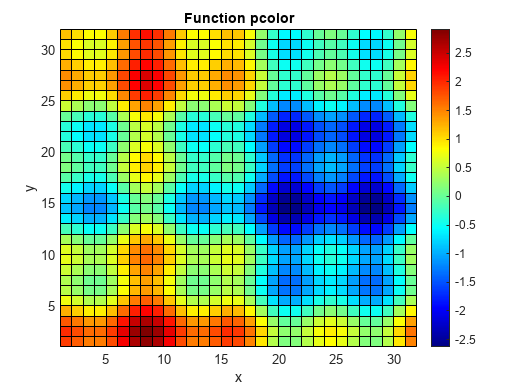

%TODO
figure;
pcolor(solutionMatrix);
title('Function pcolor');
xlabel('x');
ylabel('y');
colormap(jet);
colorbar;

Also, visualize the matrix using the matlab function surf.

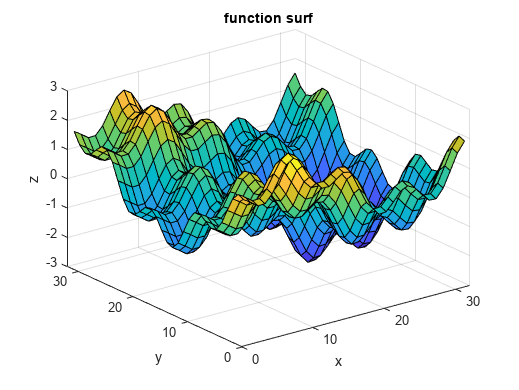

%TODO
figure;
surf(solutionMatrix);
title('function surf');
xlabel('x');
ylabel('y');
zlabel('z');

### 2b: Generate and visualize a matrix of function derivatives/gradients (5%)

As in part 1, generate 2D gradient vectors, but for the new function:


$$f\left(x,y\right)=\sin \left(\frac{\left(x*2\pi \right)}{n}\right)+0\ldotp 5*\cos \left(\frac{\left(x*8\pi \right)}{n}\right)+\cos \left(\frac{\left(y*2\pi \right)}{n}\right)+0\ldotp 5*\sin \left(\frac{\left(y*8\pi \right)}{n}\right)$$


**Hint**: *You can use wolfram alpha or any other aid to calculate the partial derivatives.*

% For each tile (x,y): x = df/dx, y = df/dy

grad_x = zeros(n);
grad_y = zeros(n);

% Compute the partial derivatives using loops
for i = 1:n
     for j = 1:n
         x1 = x1Var(j);
         y1 = y1Var(i);
         x2 = x2Var(j);
         y2 = y2Var(i);
 
 
         %% New partial derivatives calculated from wolfram alpha
        df_dx = cos(x1) * ((2*pi)/n) - sin(x2) * 0.5*((8*pi)/n);
        df_dy = cos(y2)*0.5*((8*pi)/n) - sin(y1) * ((2*pi)/n);
         
         % Calculate the gradient vector field for steepest descent (negative of the gradient)
         grad_x(i, j) = -df_dx;
         grad_y(i, j) = -df_dy;
     end
 end


%TODO

Visualize using the matlab function quiver.

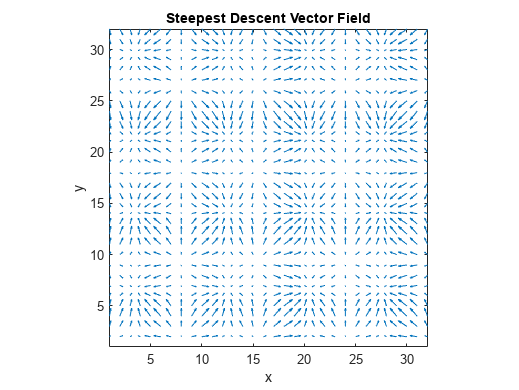

%TODO

figure;
quiver(row', row', grad_x, grad_y); 
title('Steepest Descent Vector Field');
xlabel('x');
ylabel('y');
xticks(0:5:n); yticks(0:5:n);
axis equal;
% Done to fit the figure
ax = gca;
ax.XLim = [1 n];
ax.YLim = [1 n];
ax.DataAspectRatio = [1 1 1];

### 2c: Perform gradient descent (5%)

Now, try to use the same gradient descent function you already made in this new function. Again, you are not expected to reach the optimal coordinate from any other coordinate. Use at least two different starting positions, and visualize the results in the same way as in Part 1.

%TODO

% 3 starting points
start_points = ...
    [9, 19;
    8, 2;
    25,2;
    ]

start_points =      9    19
     8     2
    25     2


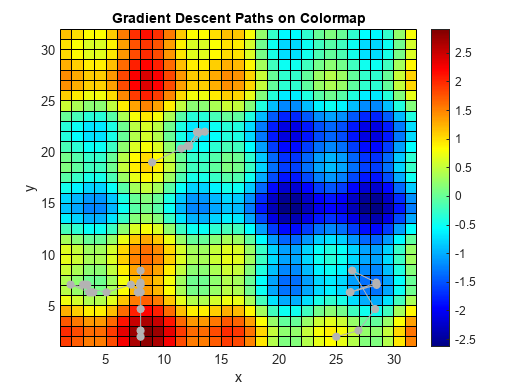

tau = 8;
max_iter = 100;


% Perform gradient descent for each starting point
paths = cell(1, 3);
for i = 1:3
    start_x = start_points(i, 1);
    start_y = start_points(i, 2);
    paths{i} = gradient_descent(start_x, start_y, grad_x, grad_y, tau, max_iter); %%Function at the end of the file
end


% Visualize the descent without gradient arrows
figure;
pcolor(solutionMatrix);
colormap(jet);
colorbar;
hold on;

% Plot the gradient descent paths with the color gray 
gray = [.7 .7 .7];
for i = 1:3
    scatter(paths{i}(:, 1), paths{i}(:, 2), 30, 'MarkerEdgeColor', gray, 'MarkerFaceColor', gray);
    plot(paths{i}(:, 1), paths{i}(:, 2), 'Color', gray);
end

hold off;
title('Gradient Descent Paths on Colormap');
xlabel('x');
ylabel('y');

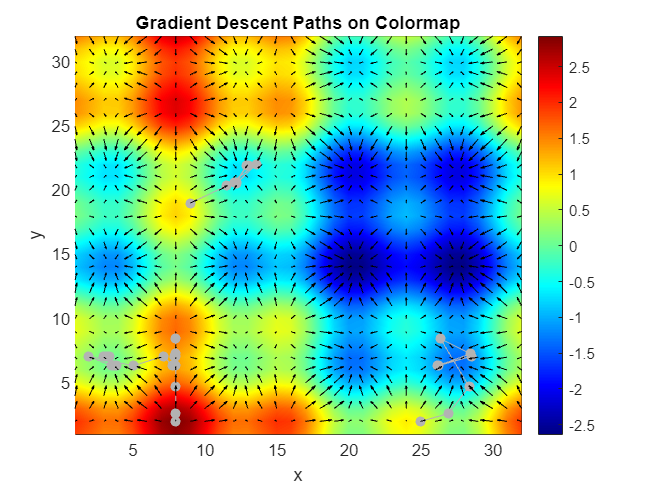





% Visualize the descent with the gradient arrows and interpolated shading.
figure;
pcolor(solutionMatrix);
shading interp;
colormap(jet);
colorbar;
hold on;

% Plot the gradient descent paths with the color gray and gradient arrows
% with black
gray = [.7 .7 .7];
for i = 1:3
    scatter(paths{i}(:, 1), paths{i}(:, 2), 30, 'MarkerEdgeColor', gray, 'MarkerFaceColor', gray);
    plot(paths{i}(:, 1), paths{i}(:, 2), 'Color', gray);
end
quiver(row', row', grad_x, grad_y, 'color', 'k');
hold off;
title('Gradient Descent Paths on Colormap');
xlabel('x');
ylabel('y');

**Q**: What issues do you find with performing gradient descent on this more complex function? Do you have any ideas how you could solve such issues?

**A**:* With the complex function it seems to be hard to converge to a global minimum, since there are so many slopes, the path often gets stuck in a local minima, maybe momentum could solve the issue of the path getting stuck in local minimums, cause then the built up momentum could help the path escape the local minimum and make its way to the global minimum or another local minimum smaler than the previous.*

*I also found out that i needed to increase my tau from 5 to reach minimums, if my tau was too small the path seemed to stop to early, while if i chose it to be too big then the path would go between different local minimums, and would not stop until the maximum iteration was reached. So to fix this i used trial and error on different tau values. Another solution could be to use optimal tau value as we did in ex4 and in the lectures. Another solution for the problem of the path going back and forth over one another could be to not use linear interpolation.*

## Part 3 - Gradient ascent (25%)

### 3a: Central difference (10%)

For this last part, start by generating a vector field based on the heightmap image "crater.png" included with the assignment. Since there is no way to "derive" an image (it is an image, not a function), you have to use the central difference method to get an estimated gradient per  pixel/coordinate instead.

Load the image as singular values into matrix.

imdata = imread('crater.png');
monoImage = im2double(rgb2gray(imdata));

Visualize the matrix using the matlab functions pcolor, colormap and colorbar. Remove the black grid from the visualization (*Hint: This property is called 'EdgeColor')*.

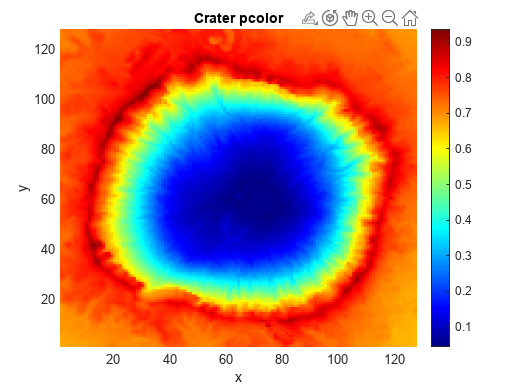

% TODO
h = pcolor(monoImage);
set(h,'edgecolor','none')
title('Crater pcolor');
xlabel('x');
ylabel('y');
colormap(jet);
colorbar;

Visualize using the matlab function surf, also here remove the black grid from the visualization.

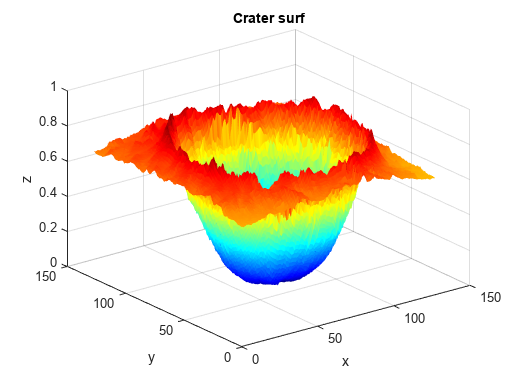

% TODO
figure;
y = surf(monoImage);
title('Crater surf');
xlabel('x');
ylabel('y');
zlabel('z');
colormap(jet);
set(y,'edgecolor','none')

Calculate approximated gradients using the central difference method and store in vector field matrix. This time, you need a loop.

**Hint**: *Calculate the central difference for a coordinate by subtracting its successor from its predecessor in each axis and halving: grad(x) = (value(x+1) - value(x-1))/2.*

%TODO
vectorFieldMatrix = zeros(128, 128, 2);
for i = 2:128-1
    for j = 2:128-1
        vectorFieldMatrix(i, j, 1) = (monoImage(i + 1, j) - monoImage(i - 1, j)) / 2;
        vectorFieldMatrix(i, j, 2) = (monoImage(i, j + 1) - monoImage(i, j - 1)) / 2;
    end
end

% Separate the x and y components of the gradient
gradient_x = vectorFieldMatrix(:, :, 1);
gradient_y = vectorFieldMatrix(:, :, 2);

Visualize using the matlab function quiver.

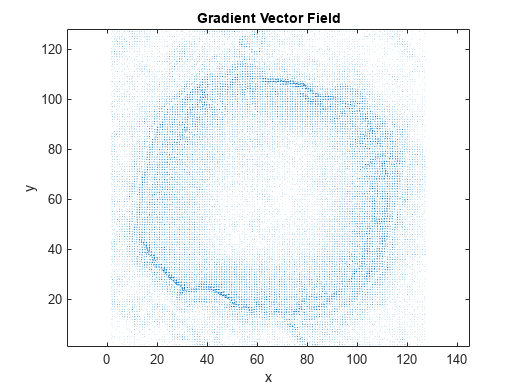

%TODO
figure;
quiver(gradient_x, gradient_y);
title('Gradient Vector Field');
xlabel('x');
ylabel('y');
axis equal;

### 3b: Gradient Ascent (15%)

Try to get out of the hole! Use one of the visualizations you created above to find at least four different starting points in the bottom of the crater (try some towards the center of the bottom and some further to the sides). Perform gradient ascent starting from each of these positions. As before, the gradients are defined for discrete coordinates, not continuously. Choose your favorite way to handle this (e.g., linear interpolation, rounding of the coordinates, etc..). Then visualize the results by plotting them on top of the colormap created in 3a.

**Q**: Will the gradient ascent take you out of the hole for any selected starting point? What are the criteria of the starting position for a successful gradient ascent?

**A**:* My four points that i found that takes me out of the crater is (60,60), (80,82), (60,90) and (80, 40). *

*It seems that we cannot find a path out of the crater if we choose a point towards the center, like for example (67,60), (75,65). (75,56), (66,65). So it seems like for us to find a path that takes us out of the crater, we need to choose points that are not at the center of the crater.*

% TODO
% 4 starting points that takes us out
 start_points = ...
     [60, 60;
     80, 82;
     60,50;
     80, 40
     ]

start_points =     60    60
    80    82
    60    50
    80    40


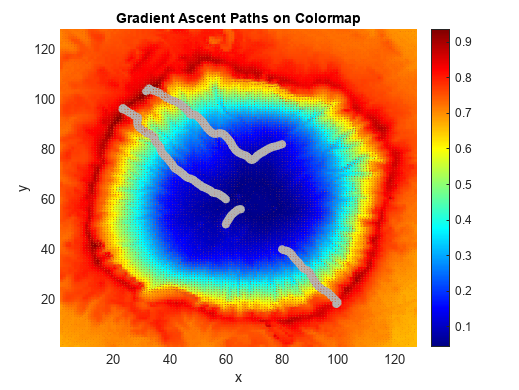


% 4 starting points that does not take us out of the crater
% start_points = ...
%     [75, 65;
%     75, 56;
%     66, 65;
%     67, 60
%     ]

tau = 25;
max_iter = 400;

% Perform gradient aescent for each starting point
paths = cell(1, 4);
for i = 1:4
    start_x = start_points(i, 1);
    start_y = start_points(i, 2);
    paths{i} = gradient_ascent(start_x, start_y, gradient_x, gradient_y, tau, max_iter); %%Function at the end of the file
end

% Visualize the aescent without gradient arrows
figure;
u=pcolor(monoImage);
set(u,'edgecolor','none')
colormap(jet);
colorbar;
hold on;

gray = [.7 .7 .7];
for i = 1:4
    scatter(paths{i}(:, 1), paths{i}(:, 2), 30, 'MarkerEdgeColor', gray, 'MarkerFaceColor', gray);
    plot(paths{i}(:, 1), paths{i}(:, 2), 'Color', gray);
end
quiver(gradient_x, gradient_y);
hold off;
title('Gradient Ascent Paths on Colormap');
xlabel('x');
ylabel('y');

**Q**:  Experiment with different step sizes (tau) and number of iterations.How do these parameters effect the ascent? What are your prefered values for these parameters (based on the experiments), and why?

**A**:* If we use to small tau or number of iterations we risk not getting out of the crater, even if there is a path. The previous values that i used for the descent (tau=5 and max_iter = 100) is way to little in this case, so we need to either increase or tau or our number of iterations. I first increased only my number of iterations but found that even then, some points that were more towards the center still did not make it out. So i increased my tau aswell. And with my mention points above i ended up with a tau of 25 and max_iteration of 400, this is tuned to my points. However if i lower my tau or max_iter it is not certain that we make it out of the crater for my mentioned points. It is also possible that we need to further increase tau and number of iterations the closer we get to the center.*

## **FUNCTIONS**

function [path] = gradient_descent(x, y, gradient_x, gradient_y, tau, max_iter)
    n = 32;
    path = [x, y];
    
    for i = 1:max_iter
        % find gradient values using linear interpolation
        gx = interp2(gradient_x, x, y, 'linear');
        gy = interp2(gradient_y, x, y, 'linear');
        
        % Update x and y using the step size (tau) and gradient values
        x = x + tau * gx;
        y = y + tau * gy;
        
        % Check if the new coordinates are within the bounds of the matrix
        if x < 1 || x > n || y < 1 || y > n
            break;
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %% Method tried first that did not give accurate end result
        %x_int = round(x);
        %y_int = round(y);
        
        
        %if x_int < 1 || x_int > n || y_int < 1 || y_int > n
        %    break;
        %end
        
        %gradient values  from the matrices
        %gx = gradient_x(y_int, x_int);
        %gy = gradient_y(y_int, x_int);

        %x = x + tau * gx;
        %y = y + tau * gy;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Add the new coordinates to the path
        path = [path; x, y];
        
        % Stop the loop early if the previous step is smaller than 0.001
        if sqrt(gy^2 + gx^2) * tau < 1e-03
            break;
        end
    end
end

function [path] = gradient_ascent(x, y, gradient_x, gradient_y, tau, max_iter)
    n = 128;
    path = [x, y];
    
    for i = 1:max_iter
        % find gradient values using linear interpolation
        gx = interp2(gradient_x, x, y, 'linear');
        gy = interp2(gradient_y, x, y, 'linear');
        
        % Update x and y using the step size (tau) and gradient values
        x = x - tau * gx;
        y = y - tau * gy;
        
        % Check if the new coordinates are within the bounds of the matrix
        if x < 1 || x > n || y < 1 || y > n
            break;
        end

        % Add the new coordinates to the path
        path = [path; x, y];
        
        % Stop the loop early if the previous step is smaller than 0.001
        if sqrt(gy^2 + gx^2) * tau < 1e-03
            break;
        end
    end
end